## Test Parseval K-SVD

- Part1: Learning a K-SVD dictionary for the initial dictionary for Parseval K-SVD

clear all
close all
clc
Im = imread('boat256.png');
Im = double(Im);

Im_block_col = im2col(Im, [8,8], 'distinct'); %Im block
Im_block_col_mean = mean(Im_block_col);
Y = Im_block_col - Im_block_col_mean; % E(Yi) = 0, for all i

%K-SVD

%create overcomplete DCT frame
Pn = 16 ;
DCT=zeros(8,Pn);
for k=0:1:Pn-1,
    V=cos([0:1:7]'*k*pi/Pn);
    if k>0, V=V-mean(V); end;
    DCT(:,k+1)=V/norm(V);
end;
DCT=kron(DCT,DCT);

param.K = 256;
param.numIteration = 30;
param.InitializationMethod =  'GivenMatrix';
param.initialDictionary = DCT;
param.displayProgress = 1;
param.preserveDCAtom = 1;
param.L = 64;
param.errorFlag = 0;
param.errorGoal = 1.0e-8;
[D_svd, output] = KSVD(Y, param);

Iteration   2   max error norm is: 1.4284e-12
Iteration   3   max error norm is: 2.4237e-12
Iteration   4   max error norm is: 1.5522e-12
Iteration   5   max error norm is: 1.3295e-12
Iteration   6   max error norm is: 1.8566e-12
Iteration   7   max error norm is: 1.9986e-12
Iteration   8   max error norm is: 3.6171e-12
Iteration   9   max error norm is: 1.4905e-12
Iteration   10   max error norm is: 2.6481e-12
Iteration   11   max error norm is: 1.7202e-12
Iteration   12   max error norm is: 1.8371e-12
Iteration   13   max error norm is: 2.5093e-12
Iteration   14   max error norm is: 1.5739e-12
Iteration   15   max error norm is: 1.3117e-12
Iteration   16   max error norm is: 2.6791e-12
Iteration   17   max error norm is: 1.9143e-12
Iteration   18   max error norm is: 4.9436e-12
Iteration   19   max error norm is: 2.0819e-12
Iteration   20   max error norm is: 1.438e-12
Iteration   21   max error norm is: 2.6277e-12
Iteration   22   max error norm is: 2.4069e-12
Iteration   23   max e

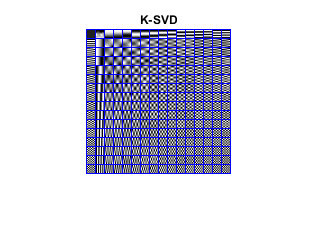

X = full(output.CoefMatrix);

KsvdIm = plot_8by8_frame(D_svd);
figure;
imshow(KsvdIm); title('K-SVD'); %show D_svd element in image

- Part2: Learning the Parseval K-SVD

Psi0 = D_svd;
Phi0 = D_svd + randn(size(D_svd, 1), size(D_svd, 2));
X0 = X;
maxIter = 50;
t = 1.0e-8;
rho = [0.1, 1.0e+5, 1.0e+5];
IsRecord = true;
ShowDetail = true;

[Psi, Phi, X, Record] = ParsevalKSVD(Y, Psi0, Phi0, X0, maxIter, t, rho, IsRecord, ShowDetail);

Iteration = 1
L=1.842e+08 , obj_rep=2.985e+06 , obj_total=3.633e+06 , con1=68.58     , con2=269.9     
Iteration = 2
L=2.807e+08 , obj_rep=1.461e+06 , obj_total=3.92e+06  , con1=284.4     , con2=125.3     
Iteration = 3
L=-7.426e+07, obj_rep=4.098e+06 , obj_total=1.014e+07 , con1=407.2     , con2=658.2     
Iteration = 4
L=1.435e+08 , obj_rep=1.03e+07  , obj_total=8.955e+06 , con1=272.8     , con2=567.7     
Iteration = 5
L=-4.627e+07, obj_rep=9.106e+06 , obj_total=1.088e+07 , con1=129.4     , con2=290       
Iteration = 6
L=-2.23e+07 , obj_rep=1.256e+07 , obj_total=9.567e+06 , con1=60.93     , con2=439.3     
Iteration = 7
L=6.06e+07  , obj_rep=1.507e+07 , obj_total=6.96e+06  , con1=65.13     , con2=309.9     
Iteration = 8
L=1.082e+08 , obj_rep=1.103e+07 , obj_total=5.912e+06 , con1=88.11     , con2=269       
Iteration = 9
L=7.711e+07 , obj_rep=6.836e+06 , obj_total=6.943e+06 , con1=50.23     , con2=417.4     
Iteration = 10
L=7.014e+07 , obj_rep=6.097e+06 , obj_total=7.466e+06 , co

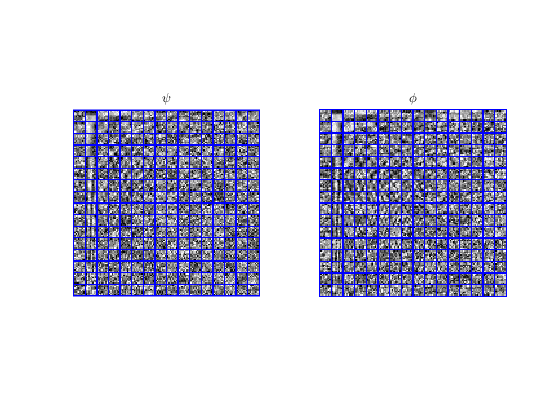


PsiIm = plot_8by8_frame(Psi); 
PhiIm = plot_8by8_frame(Phi);
figure;
subplot(1, 2, 1); imshow(PsiIm); title('$\psi$','Interpreter','latex');
subplot(1, 2, 2); imshow(PhiIm); title('$\phi$','Interpreter','latex');

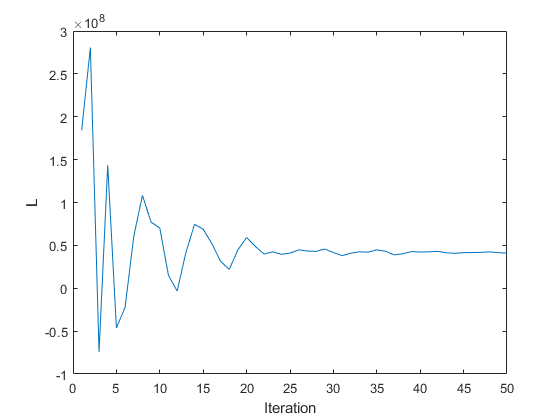


%Displaying the curve for the convergent behavior
figure;
plot(Record.augLag); xlabel('Iteration'); ylabel('L');

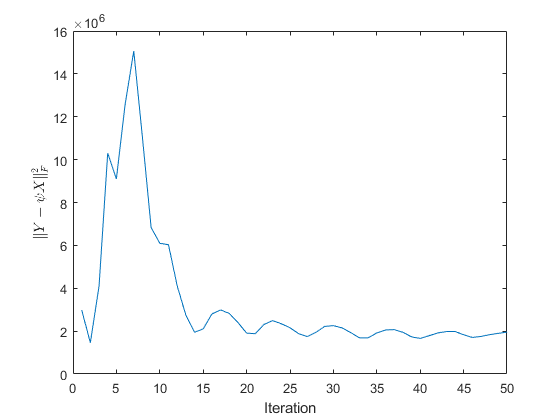


figure;
plot(Record.obj_rep); xlabel('Iteration'); ylabel('$\| Y - \psi X \|_F^2$', 'Interpreter','latex');

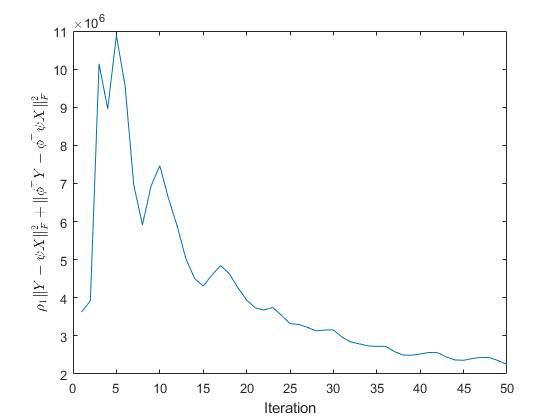


figure;
plot(Record.obj_total); xlabel('Iteration'); ylabel('$\rho_1 \| Y - \psi X \|_F^2 + \| \phi^\top Y -  \phi^\top \psi X \|_F^2$', 'Interpreter','latex');

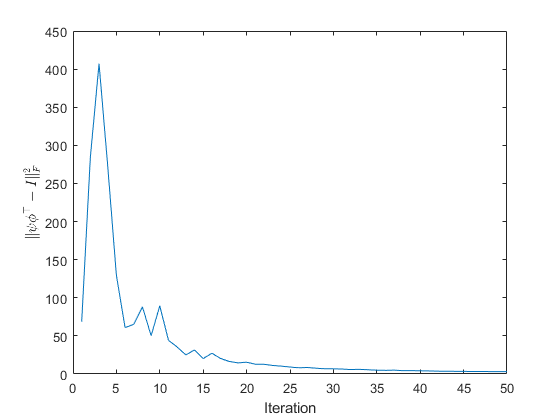


figure;
plot(Record.con1); xlabel('Iteration'); ylabel('$\| \psi \phi^\top - I \|_F^2$', 'Interpreter','latex');

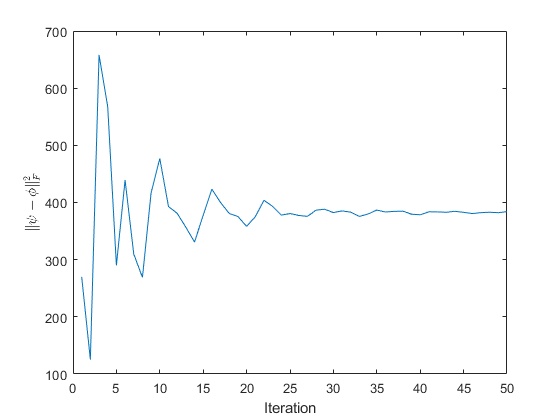


figure;
plot(Record.con2); xlabel('Iteration'); ylabel('$\| \psi - \phi \|_F^2$', 'Interpreter','latex');